# Project 11 (Two-sensor Calibration)

%{
Two sensor calibration and agreement check
   originally from ES115 Engineering Computer Applications, Module 1
   project bank, project 5
Author: Tori Testa
Version: 1.0
Date: 2026-04-04
Purpose:
   -
Input:
   -x interval
   -
Output:
   -
Engineering Algorithems:
   -
MATLAB tools/functions:
   -
%}

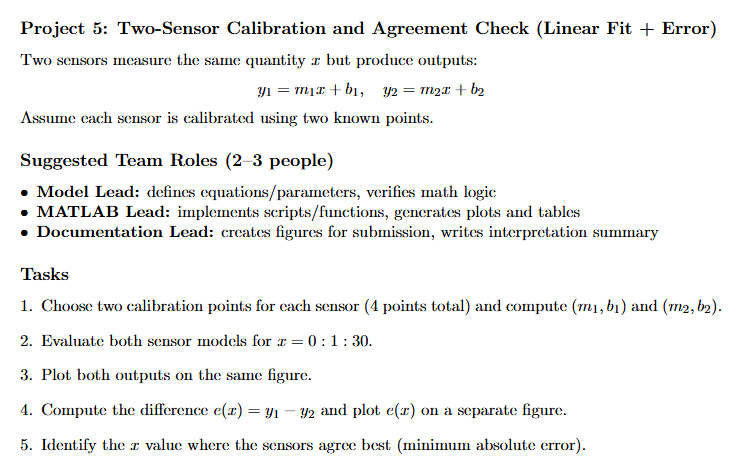

clc
clear

% the calibration points for the first sensor
x11 = 0; % defines the x coordinate of the first point
y11 = 3; % defines the y coordinate of the first point
x12 = 30; % defines the x coordinate of the second point
y12 = 66; % defines the y coordinate of the second point
m1 = (y12 - y11) / (x12 - x11); % the slope for the output of the first sensor
b1 = y11 - m1 * x11; % the y intercept for the output of the first sensor
% the calibration points for the second sensor
x21 = 0; % defines the x coordinate of the first point
y21 = 7; % defines the y coordinate of the first point
x22 = 30; % defines the x coordinate of the second point
y22 = 57; % defines the y coordinate of the second point
m2 = (y22 - y21) / (x22 - x21); % the slope for the output of the second sensor
b2 = y21 - m2 * x21; % the y intercept for the output of the second sensor

% evaluate both sensor models for x
x = 0:1:30; % defines x on the interval 0 to 30
y1 = (m1 * x) + b1; % defines the equation for sensor one's output
y2 =(m2 * x) + b2; % defines the equation for sensor two's output

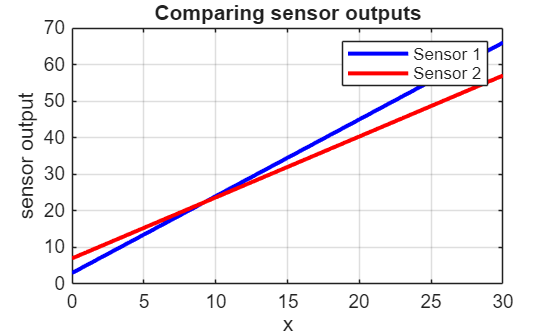

% plot both outputs on same plot

% plots sensor one output
plot(x, y1, 'b-', 'linewidth', 2) % the line is blue with a width of 2
title('Comparing sensor outputs') % creates a title for the graph
xlabel('x') % labels the x axis
ylabel('sensor output') % labels the y axis
grid on % shows the grid lines on the plot
hold on % allows for both lines to be plotted on the same graph
% plots sensor two output
plot(x, y2, 'r-', 'linewidth', 2) % the line is red with a width of 2
legend('Sensor 1', 'Sensor 2') % creates a legend that labels what each line represents
hold off % stops anything past this from being graphed on the same plot

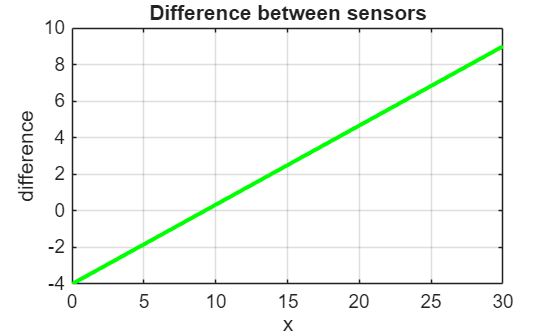

% compute difference between two and plot
dif = y1 - y2; % finds the difference between the outputs of the two sensors

% plots the difference between the two outputs
plot(x, dif, 'g-', 'linewidth', 2) % makes the line green with a width of 2
title('Difference between sensors') % titles the plot
ylabel('difference') % labels the y axis 'difference'
xlabel('x') % labels the x axis
grid on % turns the grid lines on

% identify x for where sensors agree best (min absolue error)
[~, idx] = min(abs(dif)); % finds the index of the absolute minimum difference between the two sensors
x_best = x(idx);  % finds the x where the sensors agree best
min_error = dif(idx); % the error at the best matching point
fprintf('The sensors agree best at x = %g', min_error) % displays where the sensors agree best

The sensors agree best at x = -0.1